%addpath 'iwave\development\matlab'

load_parameters

t_end = 0.01; % secs
t = 0 : t_step : t_end

t =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


reps = 10;

Q_orig = 1e6;
Q = Q_orig / heterodyning_ratio;

band_width = f_a / Q % or f_a_original / Q_orig

band_width = 483.5590


T = 10e-3;

tau = 0.0143e-3;

f_0s = linspace(f_a - 3*band_width, f_a + 3*band_width, 20);
L_f0s = length(f_0s);

snr_dynamics = zeros(reps, L_f0s);
snr_statics  = zeros(reps, L_f0s);
power_just_noise = zeros(reps, 1);

start_secs = 0.0015;
assert(start_secs < t(end)/3);
start = round(start_secs * f_sampling);

done = 0;
num_runs = reps * L_f0s

num_runs = 200

tic

for l = 1 : reps
    f_axion = generate_axion_frequency_maxwellian(t, f_sampling, t_coherence, f_a, axion_linewidth);
    signal = generate_axion_signal(t, f_sampling, f_axion, axion_power_over_Q * Q_orig);
    noise_power = calculate_noise_power(f_sampling, T);
    noise = generate_thermal_noise(t, noise_power);
    p_s = bandpower(signal)
    p_n = bandpower(noise)
    
    noise_resonated  = resonator_2(noise, f_0s(1),   band_width, f_sampling);
    noise_resonated2 = resonator_2(noise, f_0s(end), band_width, f_sampling);
    power_just_noise  = bandpower(noise_resonated (start:end))
    power_just_noise2 = bandpower(noise_resonated2(start:end))
    
    parfor i = 1 : L_f0s
        f_0 = f_0s(i);

        limiting_band = [f_0-band_width, f_0+band_width];

        [f_iwave, signal_dynamic] = do_iwave_and_resonator(t, noise, signal, f_0, band_width, f_sampling, limiting_band, tau);
        signal_static = resonator_2(noise + signal, f_0, band_width, f_sampling);

        snr_dynamics(l, i) = bandpower(signal_dynamic(start:end)) / power_just_noise - 1;
        snr_statics (l, i) = bandpower(signal_static (start:end)) / power_just_noise - 1;
    end
    done = done + L_f0s;
    frac_done = done/num_runs;
    timer_elapsed = toc;
    time_total = timer_elapsed / frac_done;
    time_remaining = time_total - timer_elapsed;
    fprintf('done %d%%, %d min gone, %d min rem\n', round(100*frac_done), round(timer_elapsed/60), round(time_remaining/60))
    
end

p_s = 1.4286e-20

p_n = 1.5804e-17

power_just_noise = 8.6904e-23

power_just_noise2 = 1.4216e-22

done 10%, 1 min gone, 7 min rem


p_s = 1.4286e-20

p_n = 1.5848e-17

power_just_noise = 9.2584e-23

power_just_noise2 = 1.2401e-22

done 20%, 2 min gone, 6 min rem


p_s = 1.4286e-20

p_n = 1.5848e-17

power_just_noise = 8.3315e-23

power_just_noise2 = 8.4565e-23

done 30%, 2 min gone, 6 min rem


p_s = 1.4286e-20

p_n = 1.5833e-17

power_just_noise = 9.5230e-23

power_just_noise2 = 9.4327e-23

done 40%, 3 min gone, 5 min rem


p_s = 1.4286e-20

p_n = 1.5854e-17

power_just_noise = 1.0169e-22

power_just_noise2 = 9.0015e-23

done 50%, 4 min gone, 4 min rem


p_s = 1.4286e-20

p_n = 1.5817e-17

power_just_noise = 8.4894e-23

power_just_noise2 = 1.2788e-22

done 60%, 5 min gone, 3 min rem


p_s = 1.4286e-20

p_n = 1.5855e-17

power_just_noise = 1.6899e-22

power_just_noise2 = 6.7597e-23

done 70%, 6 min gone, 2 min rem


p_s = 1.4286e-20

p_n = 1.5863e-17

power_just_noise = 8.5084e-23

power_just_noise2 = 7.6858e-23

done 80%, 6 min gone, 2 min rem


p_s = 1.4286e-20

p_n = 1.5842e-17

power_just_noise = 1.4877e-22

power_just_noise2 = 7.2370e-23

done 90%, 7 min gone, 1 min rem


p_s = 1.4286e-20

p_n = 1.5850e-17

power_just_noise = 8.8087e-23

power_just_noise2 = 6.3973e-23

done 100%, 8 min gone, 0 min rem


snr_dynamic    = mean(snr_dynamics, 1);
snr_dynamic_err = std(snr_dynamics, 1);
snr_static     = mean(snr_statics,  1);
snr_static_err  = std(snr_statics,  1);
s_d_over_s_s = snr_dynamic ./ snr_static;

figure
c = colororder

c =          0    0.4470    0.7410
    0.8500    0.3250    0.0980
    0.9290    0.6940    0.1250
    0.4940    0.1840    0.5560
    0.4660    0.6740    0.1880
    0.3010    0.7450    0.9330
    0.6350    0.0780    0.1840


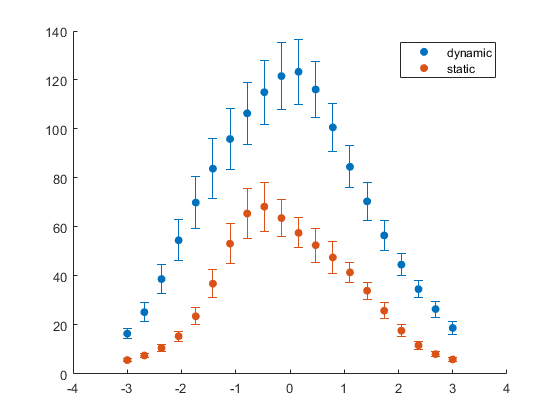

df = f_a / Q;
scatter((f_0s-f_a)/df, snr_dynamic, [], c(1,:), 'filled')
hold on
scatter((f_0s-f_a)/df, snr_static,  [], c(2,:), 'filled')
errorbar((f_0s-f_a)/df, snr_dynamic, snr_dynamic_err/2, 'color',c(1,:), 'LineStyle','none', 'HandleVisibility',"off")
errorbar((f_0s-f_a)/df, snr_static,  snr_static_err/2,  'color',c(2,:), 'LineStyle','none', 'HandleVisibility',"off")
legend('dynamic', 'static')

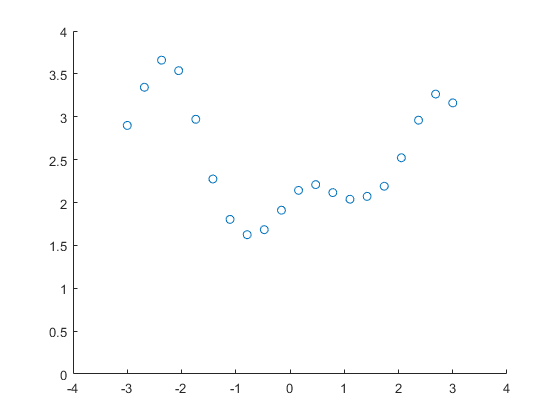

figure
scatter((f_0s-f_a)/df, s_d_over_s_s)
y_lim = ylim();
ylim([0, y_lim(2)])